# サッカー国際試合の対戦関係を図示する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;

csvファイルをtable形式で読み込む

opts = detectImportOptions('../data/archive/results.csv');
opts = setvaropts(opts, 'date', 'InputFormat', 'yyyy/MM/dd');

tbl=readtable('../data/archive/results.csv',opts)

tbl = 47598×9 table
       date        home_team       away_team      home_score    away_score     tournament        city          country        neutral 
    __________    ____________    ____________    __________    __________    ____________    ___________    ____________    _________

    1872/11/30    {'Scotland'}    {'England' }        0             0         {'Friendly'}    {'Glasgow'}    {'Scotland'}    {'FALSE'}
    1873/03/08    {'England' }    {'Scotland'}        4             2         {'Friendly'}    {'London' }    {'England' }    {'FALSE'}
    1874/03/07    {'Scotland'}    {'England' }        2             1         {'Friendly'}    {'Glasgow'}    {'Scotland'}    {'FALSE'}
    1875/03/06    {'England' }    {'Scotland'}        2             2         {'Friendly'}    {'London' }    {'England' }    {'FALSE'}
    1876/03/04    {'Scotland'}    {'England' }        3             0         {'Friendly'}    {'Glasgow'}    {'Scotland'}    {'FALSE'}
    1876/03/25    {'Scotland'}    


tbl2=readtable('../data/archive/results.csv',opts);

最近の結果のみ取り出す

tbl=tbl(tbl.date>=datetime(2020,1,1),:)

tbl = 4290×9 table
       date           home_team               away_team           home_score    away_score          tournament               city              country          neutral 
    __________    _________________    _______________________    __________    __________    _______________________    _____________    _________________    _________

    2020/01/07    {'Barbados'     }    {'Canada'             }        1             4         {'Friendly'           }    {'Irvine'   }    {'United States'}    {'TRUE' }
    2020/01/09    {'Moldova'      }    {'Sweden'             }        0             1         {'Friendly'           }    {'Doha'     }    {'Qatar'        }    {'TRUE' }
    2020/01/10    {'Barbados'     }    {'Canada'             }        1             4         {'Friendly'           }    {'Irvine'   }    {'United States'}    {'TRUE' }
    2020/01/12    {'Kosovo'       }    {'Sweden'             }        0             1         {'Friendly'           }    {'Doha'     } 

tbl.home_team=categorical(tbl.home_team);
tbl.away_team=categorical(tbl.away_team);

対戦回数の計算

[C,ia,ic]=unique([tbl.home_team tbl.away_team],'rows')

C = 3477×2 の categorical 配列
     Afghanistan      Cambodia       
     Afghanistan      India          
     Afghanistan      Kuwait         
     Afghanistan      Mongolia       
     Afghanistan      Oman           
     Afghanistan      Qatar          
     Albania          Andorra        
     Albania          Armenia        
     Albania          Azerbaijan     
     Albania          Belarus        
     Albania          Bulgaria       
     Albania          Chile          
     Albania          Czech Republic 
     Albania          England        
     Albania          Estonia        
     Albania          Faroe Islands  
     Albania          Georgia        
     Albania          Hungary        
     Albania          Iceland        
     Albania          Israel         
     Albania          Italy          
     Albania          Kazakhstan     
     Albania          Kosovo         
     Albania          Liechtenstein  
     Albania          Lithuania      
     Albania          

ia =         2039
        3656
        3425
        3118
         714
        3849
        1354
        2311
        3873
         344


ic =          280
        2059
         280
        1685
         545
         913
        3309
        1167
        3278
        2606


a_counts = accumarray(ic,1);
[val,ind]=max(a_counts);
G=graph(C(:,1),C(:,2));
G.Edges.Weight=a_counts;

期間内で最も対戦している組み合わせとその試合数

G.Edges.EndNodes(ind,:)

ans = 1×2 の cell 配列
    {'Bolivia'}    {'Ecuador'}


val

val = 6

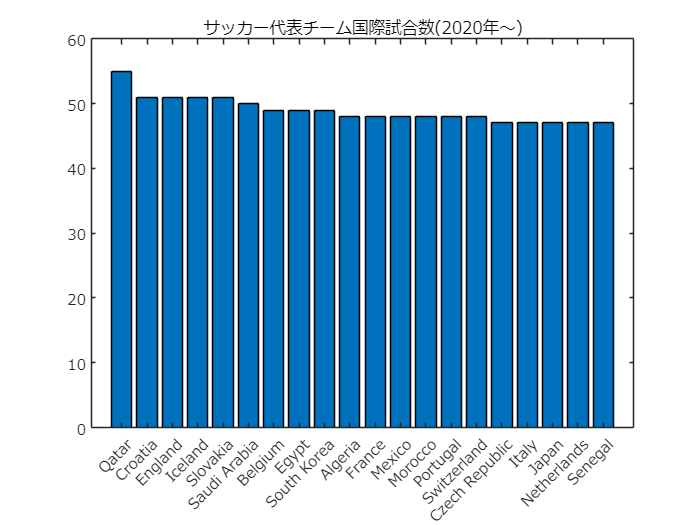

[val,ind]=sort(degree(G),'descend');
figure
bar(1:20, val(1:20));
xticks(1:20);xticklabels(G.Nodes.Name(ind(1:20)));
set(gca,'fontname','メイリオ');title('サッカー代表チーム国際試合数(2020年～)');
exportgraphics(gcf,'fig_numMatches_2020_.pdf');

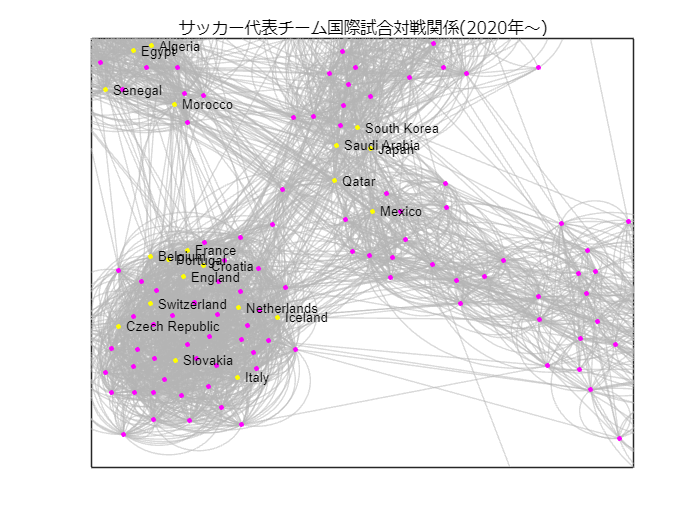


h=plot(G,"Layout","force",'LineWidth',G.Edges.Weight*0.01);
h.EdgeColor=0.7*[1 1 1];
h.NodeCData=0*ones(size(G.Nodes,1),1);
h.NodeCData(ind(1:20))=1;

h.NodeLabel=strings(size(G.Nodes,1),1);
h.NodeLabel(ind(1:20))=G.Nodes.Name(ind(1:20));

colormap("spring");
title('サッカー代表チーム国際試合対戦関係(2020年～)');
set(gca,'FontName','メイリオ');
xlim([0.63 10.01])
ylim([1.28 10.05])
exportgraphics(gcf,'fig_numH2HMatches_2020_.pdf');

xlim([2.61 5.89])
ylim([2.55 5.63])
exportgraphics(gcf,'fig_numH2HMatches_2020_enlarged.pdf');

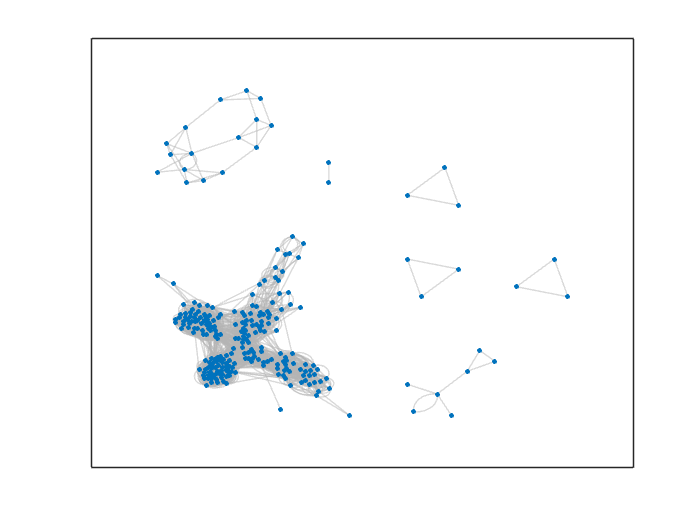

G2=graph(tbl2.home_team,tbl2.away_team);
h2=plot(G,"Layout","force",'LineWidth',G.Edges.Weight*0.01);
h2.EdgeColor=0.7*[1 1 1];
colormap("spring");

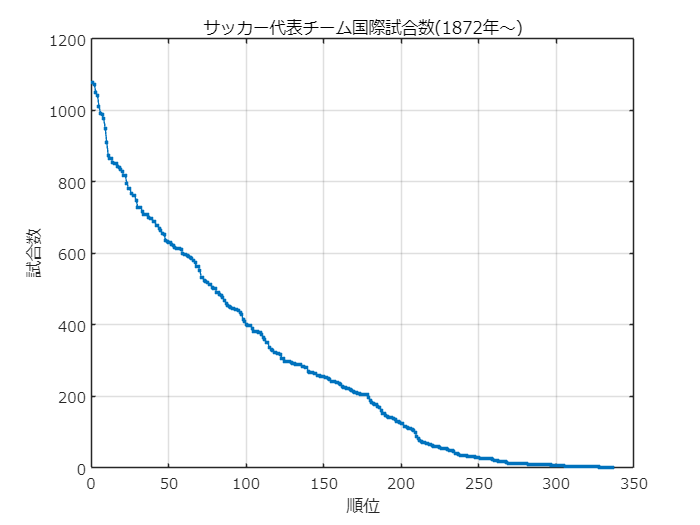

figure;
plot(sort(degree(G2),'descend'),'.-');grid on;
set(gca,'fontname','メイリオ');
ylabel('試合数');
xlabel('順位');title('サッカー代表チーム国際試合数(1872年～)')